% Getting topox and topoy and threshold files, re-sizing them
addpath F:\Kristen\Widefield2\balldata_G6H277RT
% addpath F:\Kristen\Widefield2\balldatathe_EE1LT
% addpath F:\Kristen\Widefield2\balldata_EE81LT

close all
clear all

% navigate to ball data folder, then back to WF2
load('G6H277RT_subj.mat')
% doBehavior generates one of these files per session:
load('20210311T161951_5.mat') % 277RT 031121
% load('20210107T155415_1.mat') % 277rt 010721
% load('20210204T131006_5.mat') % 277rt 020421
% load('20210107T140819_6.mat') % EE81LT 010721 (file acccidentally named 010621)
% load('20210204T164434_3.mat') % EE1LT 020421

[f p] = uigetfile('*.mat','topox maps file')

f = 031121_G6H277RT_RIG2_TOPOXmaps.mat

p = F:\Kristen\Widefield2\031121_G6H277RT_RIG2\031121_G6H277RT_RIG2_TOPOX\

load(fullfile(p,f),'mapNorm');
topox = polarMap(mapNorm{3}); % polar map = projecting features from plane to sphere

f1 = figure

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [465.6667 460.3333 573.3333 436.6667]
       Units: 'pixels'

  Show all properties


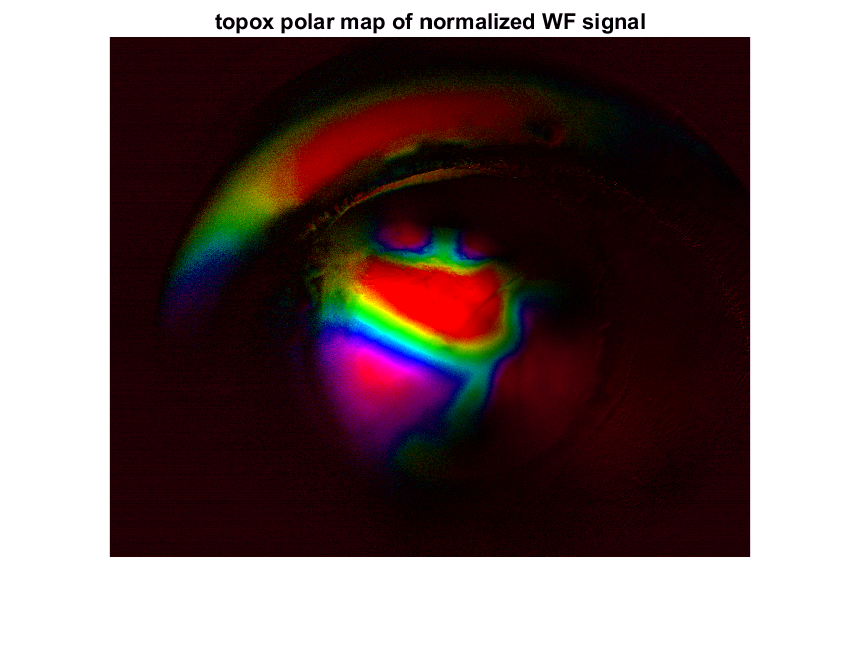

imshow(topox)
title('topox polar map of normalized WF signal')


% savefig('EE8LT_020421_topoX_retinotopy_imThreshPass') % hard coding

[f p] = uigetfile('*.mat','topoy maps file')

f = 031121_G6H277RT_RIG2_TOPOYmaps.mat

p = F:\Kristen\Widefield2\031121_G6H277RT_RIG2\031121_G6H277RT_RIG2_TOPOY\

load(fullfile(p,f),'mapNorm','map');
topoy = polarMap(mapNorm{3});

f2 = figure

f2 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [465.6667 460.3333 573.3333 436.6667]
       Units: 'pixels'

  Show all properties


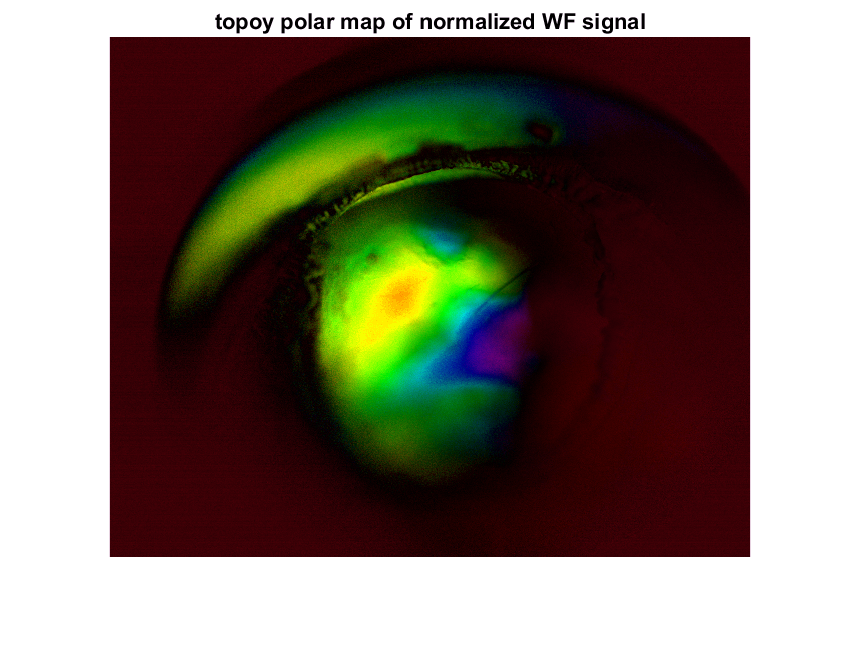

imshow(topoy)
title('topoy polar map of normalized WF signal')


% savefig('EE8LT_020421_topoY_retinotopy_imThreshPass')

[f p] = uigetfile('*.mat','maps file');

downsize = 0.25; % why resize by this factor?
load(fullfile(p,f));
df = imresize(dfof_bg,downsize);
topox = imresize(topox,downsize);
topoy = imresize(topoy,downsize);

% save('277RT_020421_1stVars_imThreshPass')

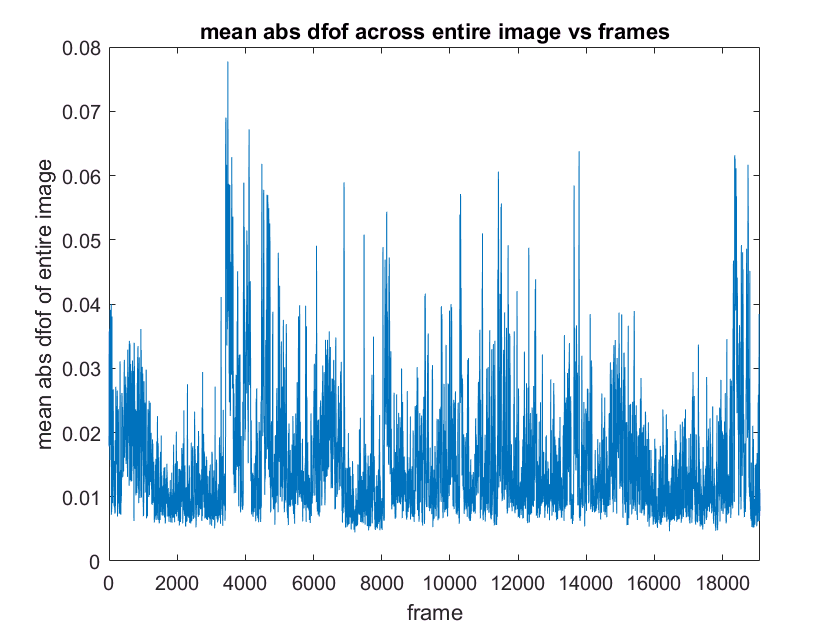

mn = mean(mean(abs(df),2),1); % taking the average of the entire imaging field over time
figure
plot(squeeze(mn)); title('mean abs dfof across entire image vs frames'); 
ylabel('mean abs dfof of entire image') 
xlabel('frame') 
xlim([0 size(squeeze(mn),1)])  


% savefig('EE8LT_020421_meanWholeImageVsFrames_imThreshPass')


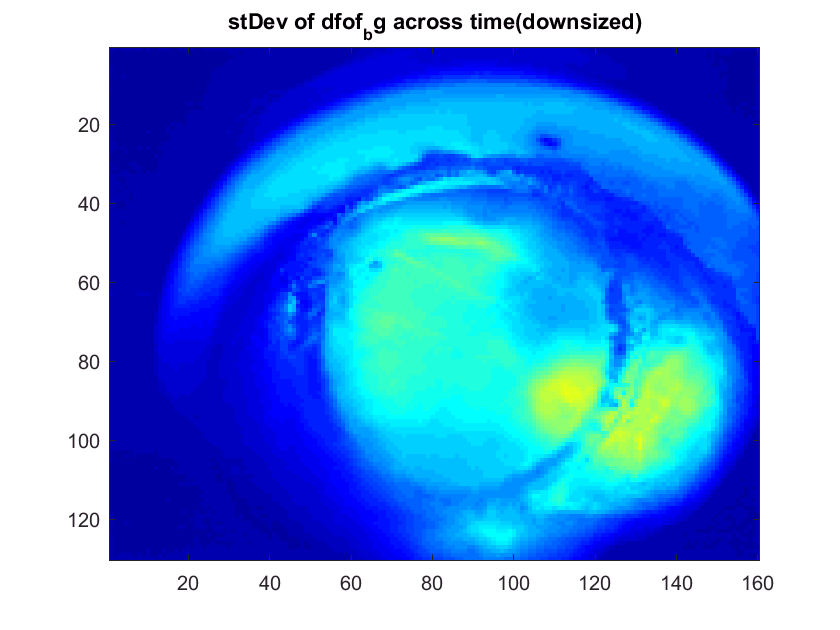

% std gives us a general sense of how much variation there is across al trials
% we also use this to crop in next section
stdMap = std(df(:,:,1:10:end),[],3); % only take every 10 frames (don't need all, why?). taking std across 3rd dimension, time
figure;
colormap jet
imagesc(stdMap,[0 0.1])
title('stDev of dfof_bg across time(downsized)')


% savefig('EE8LT_020421_stDev_of_Dfof_overtime_imThreshPass')


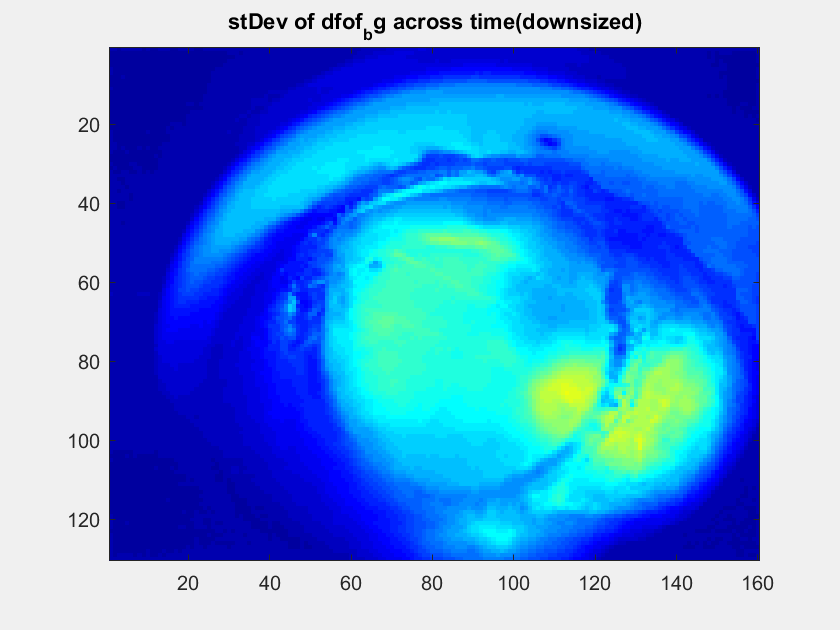

[x y] = ginput(2);

df = df(y(1):y(2),x(1):x(2),:); % cropping df to be area I select 

topox_crop = topox(y(1):y(2),x(1):x(2),:);

topoy_crop = topoy(y(1):y(2),x(1):x(2),:);

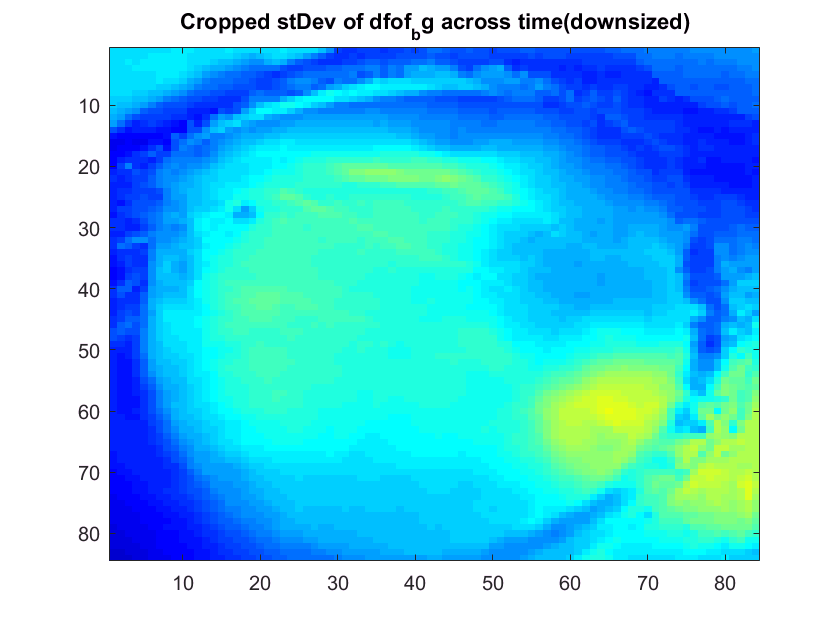

% crop manually by picking top left and then bottom right corners of a rectangle
stdMap = std(df(:,:,1:10:end),[],3); % gonna show image of std of croppoed df over time
figure
colormap jet
imagesc(stdMap,[0 0.1])
title('Cropped stDev of dfof_bg across time(downsized)') % axes are pixels?


% savefig('EE8LT_020421_CROP_stDev_of_Dfof_overtime_imThreshPass')


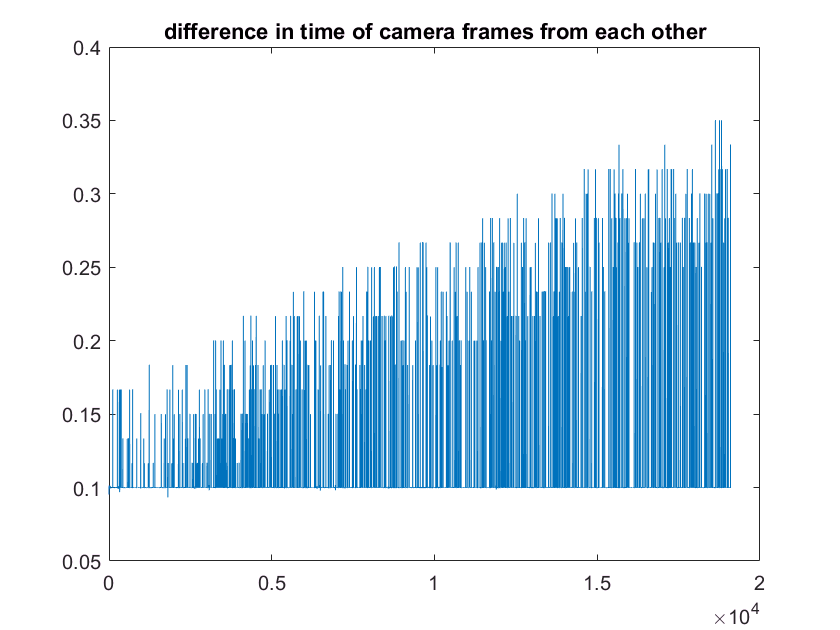

% to make sure our imaging frames are equal intervals apart
frameT = frameT-frameT(1);  %%% time of camera frames;
figure
plot(diff(frameT)) % plotting the difference between each successive value in frameT
title('difference in time of camera frames from each other')


% savefig('EE8LT_020421_camFrameDiffTime_imThreshPass')


% stimDetails = information for each condition
% allStop.frameT = time (in absolute value) of each imaging frame, beginning  at start of stopping period
% allResp.frameT = time (in absolute value) of each stim frame, beginning  at start of stopping period

% allStop relates to the imaging frames (10 Hz)
% whereas allResp relates to stimulus frames (60 Hz)

% in both allResp & allStop, frameT is a 1 x # frames during trial vector. In the
% vector, values repeat over multiple cells consecutively, but the do increase overall. 
% in allResp, it takes ~57 frames for the cell value to increase by 1. This is close to 60 Hz?
% getting values from 50-80 when i do the same for allStop - what causes the frame 
% values to increase when they do?

clear onsets

% starting gun - t0 is the first frame a stim comes on (rows in allStop = trials)
% I think allStop is in order of stims presented
t0 = allStop(1).frameT(1);  

% time of every imaging (? stimulus ?)frame realtive to stim onset (zero being stim onset)
for i = 1:length(allResp); 
    % onset = time of first frame for each stimulus presentation minus of time of first frame 
    % (stim onset relative to first frame when stim comes on) 
    onsets(i) = allResp(i).frameT(1)-t0; 
    
end % now have onset times for eact stim, in frames

% redefine onsets to not include any trials
%that have less than 11 frames before the onset
% of the stim 
idxOnsetsMoreThan10 = find(onsets>10);
%%%%onsets = onsets(idxOnsetsMoreThan10);

% instead of onsets-1, redefine onsets to
% get rid of trials where the trial frame value + 40 
% is larger than the largest onsets value
idxOnsetsCanAdd40 = find(onsets+40<max(onsets));
onsets = onsets(idxOnsetsCanAdd40);

% fir use later to index into onlyO
idxOnsetsMeetBothCriteria = intersect(idxOnsetsMoreThan10,idxOnsetsCanAdd40);
onsets = onsets(idxOnsetsMeetBothCriteria);



clear onsetDf
clear onsetFrame
clear i
    % for EE81LT on 010621, we have to leave out the last trial because
    % there are not 40 frames after it (df is shorter than last frame
    % number in onsets + 40 
for i = 1:length(onsets); % for each onset time of each respons
   
    % now we're getting the matching imaging frames for that stim onset 
    % time... the innermost part is saying find indicies for all frames 
    % that are after the onset of stim
    
    % so I guess, some onset of frames are less than ten frames before
    % the stim onset. That makes sense if the first stim onset was before 10 frames 
    % in.
    % so later on we get a problem (zero and negative values)with trying to subtract 
    % 10 from onsetFrame(i) when i is a low value.
    % so we're going to redefine onsetFrame to include only values greater than 
    % 11, so if we subtract 10 from it we'll still be greater than zero
    % we're basically potentialy excluing the first few trials (mostl likely 1 trial)
    
    % find the index for all frames that come after the i-th stim onset (but won't
    % that bleed into other stim presentations? Maybe not because allStop.frameT(i)
    % are rows for each trial?
    % when i = 1, I already get back a 1 x 658 (trials) vector
    % but onsets(i) is just a single value (why is it not zero though since it's
    % the first onset & the code in the block above this gathered all the stim
    % presentation times and subtracted them from the first stim presentation...
    % so the first value should be zero...?
    
    % extract frameT values that come after the stimulus onset
    % take the difference between each frame (why?)
    % what matrix is 'find' getting indicies for here?
    onsetFrame(i) = find(diff(frameT>onsets(i))); % I don't understand the results of the steps on this right hand side of the expression
    % I think in onsetFrame, each row collects all the frame values for frames in
    % that stim presentation/trial (so long as they occur after the actual onset,
    % b/c the imaging & camera frames are not totally synced
    % (Q: is trial duration the stim presentation + following ISI?)
 
    % now we're storing each chunk (10 frames behind onset and 40 frames ahead - this captures the whole stim evoked response
    % so, onset Df is yet another subsection of dfof_bg, just aorund onset frame time only
    onsetDf(:,:,:,i) = df(:,:,onsetFrame(i)-10:onsetFrame(i)+40);
   
end


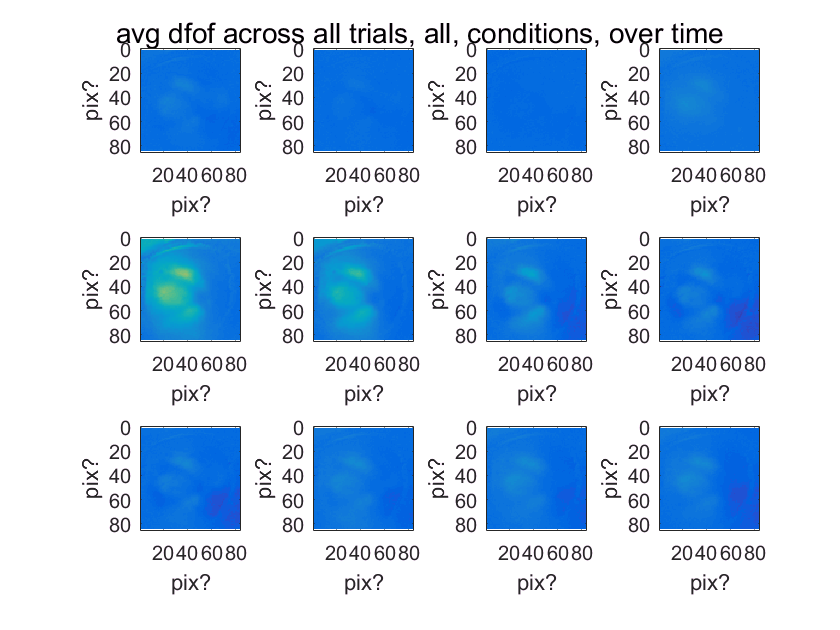


figure
suptitle('avg dfof across all trials, all, conditions, over time')
for f = 1:12; % why 12 - 12 times points just good number for display
    subplot(3,4,f) % each plot is a further point in time
    % Mult time dimesion by 3 times f because we don't want to plot all the
    % frames - notice that we're taking the mean across 4th dimension, so
    % we're taking every 3rd frame averaged across *all* stimulus presnetiations 
    % 11 is because we took 10 frames before stim onset and here we're subtracting onset of stim from baseline
    % baseline is the average activity at each time point across this 5 sec interval that
    % includes pre & post stim onset. the mean activity right after stim
    % onset is subtracted from that baseline
    % wait think I got it - subtracting start of stim from all other time points.. 
    % switches from neg to pos when stim comes on so the baseline is stim onset? 
    % (kinda confused here... we're subtracting the same onset stim point from every 3rd frame... why?
    imagesc(mean(onsetDf(:,:,f*3,:),4)-mean(onsetDf(:,:,11,:),4) ,[-0.01 0.05]) 
    axis equal
    xlabel('pix?') 
    ylabel('pix?') 
end

% savefig('EE8LT_020421_meanDfof_allTrialsCondsOverTime_imThreshPass')


% collecting columns with target & contrast values
for i=1:length(stimDetails); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
    tc(i) = stimDetails(i).targContrast; % making vector with list of targ contrast for each condition
    fc(i) = stimDetails(i).flankContrast;
end

tcTrial = tc(trialCond); % use trial cond to index into correct target contrast value for that condition
fcTrial = fc(trialCond);


range = [0 0.1]; 


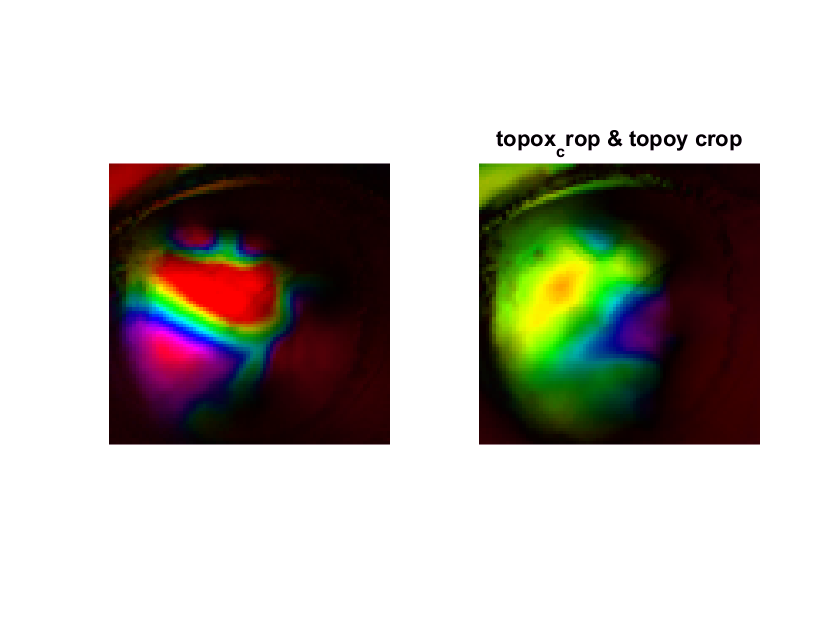

% show topox topoy crop
figure
subplot(1,2,1);
imshow(topox_crop);
subplot(1,2,2);
imshow(topoy_crop);
title('topox_crop & topoy crop');

i = 1

i = 2

i = 3

i = 4

i = 5

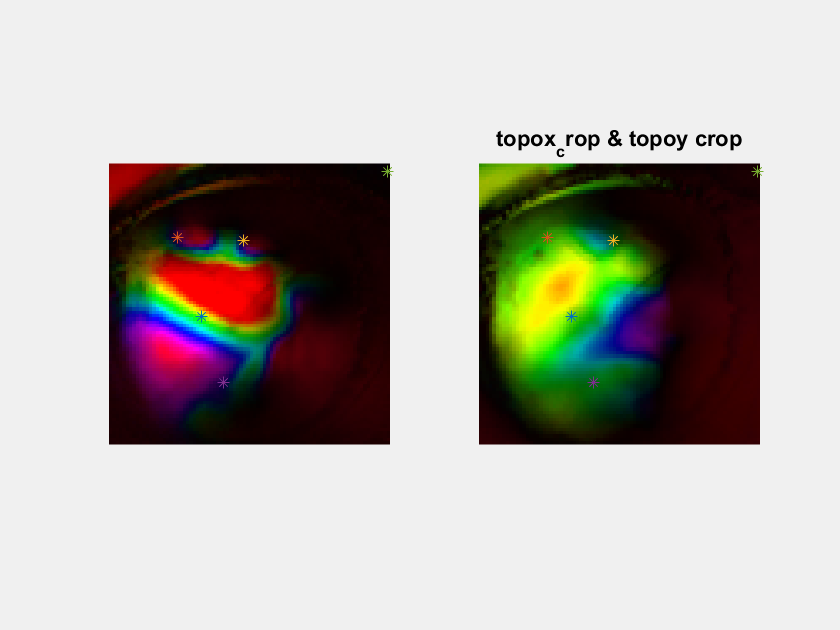

% pick 5 pts - V1, motor ctx, 3 HVAs
clear xpts ypts 
for i = 1:5
    i
    [xpts(i) ypts(i)] = ginput(1);
    for s = 1:2
        subplot(1,2,s)
        hold on
        plot(xpts(i),ypts(i),'*');
    end
end

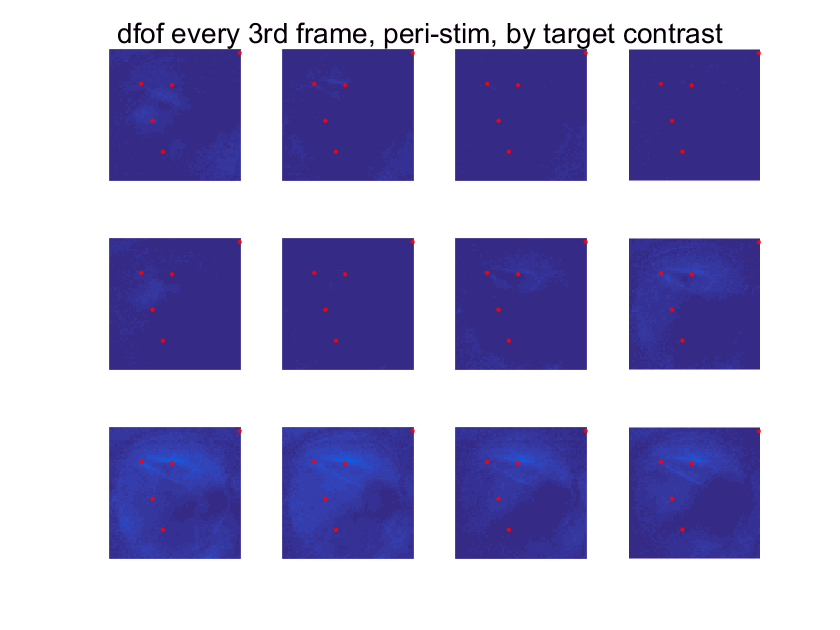

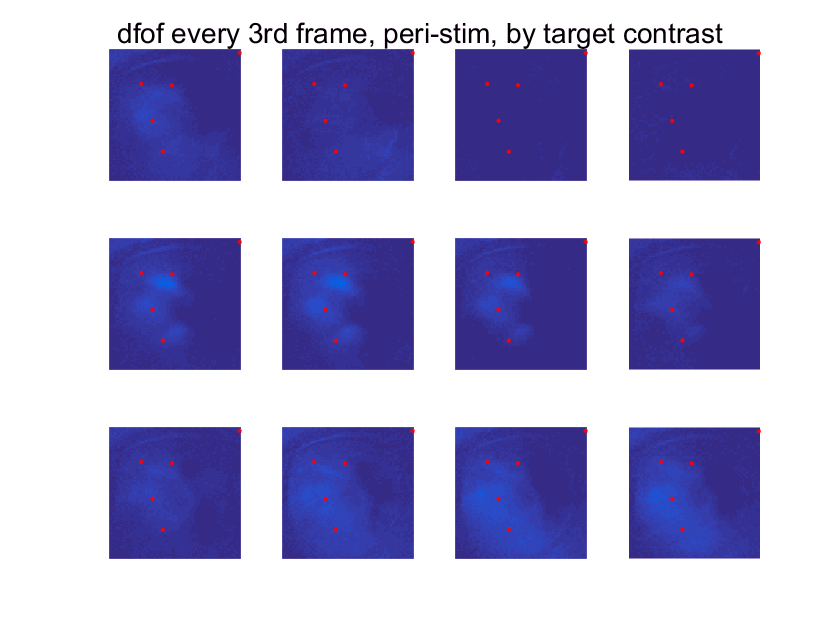

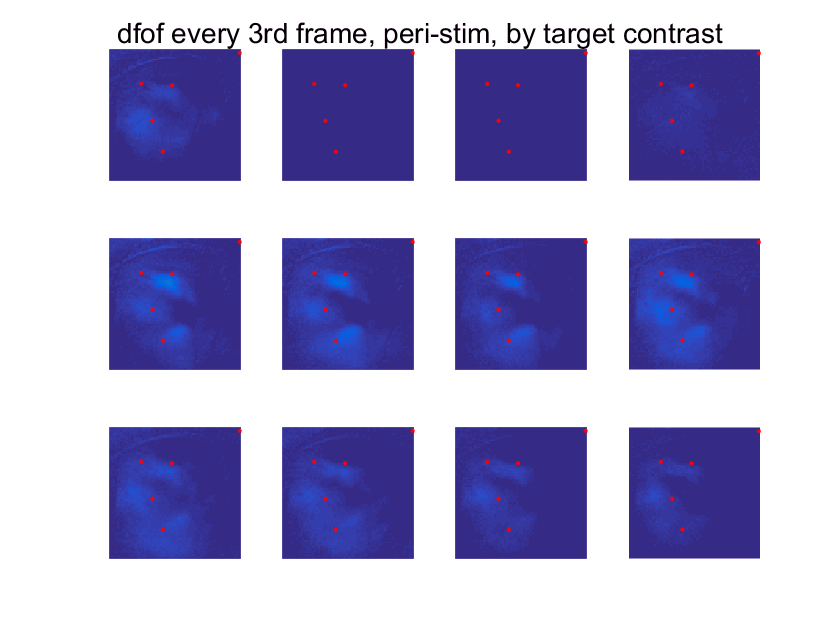

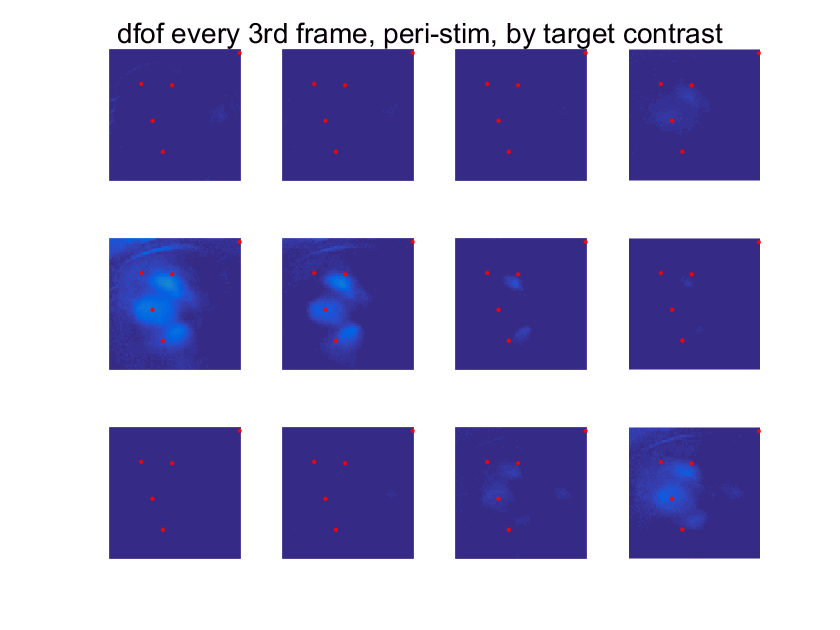

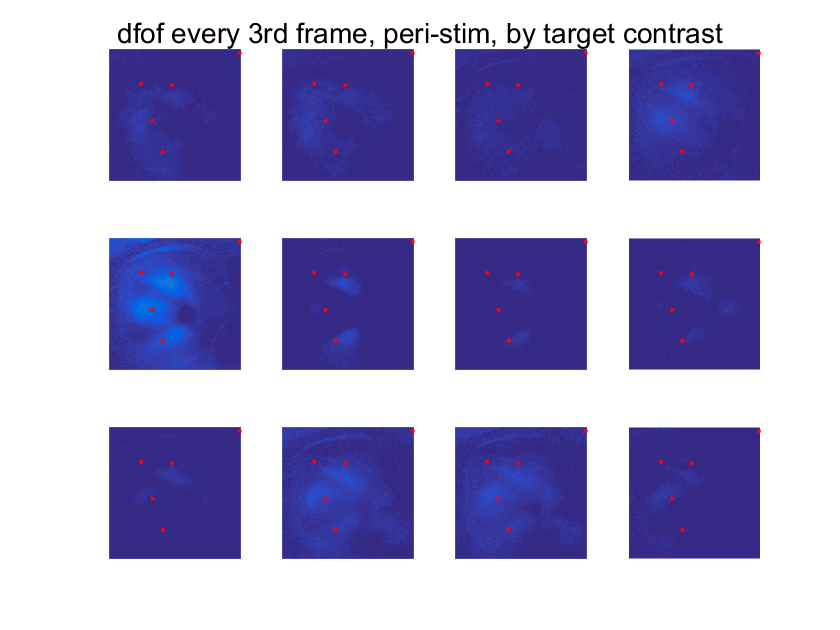

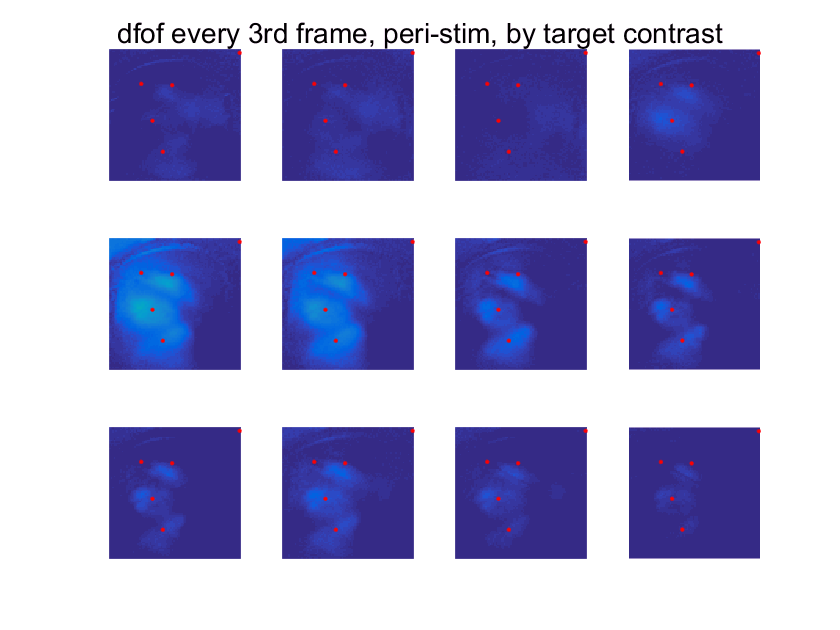

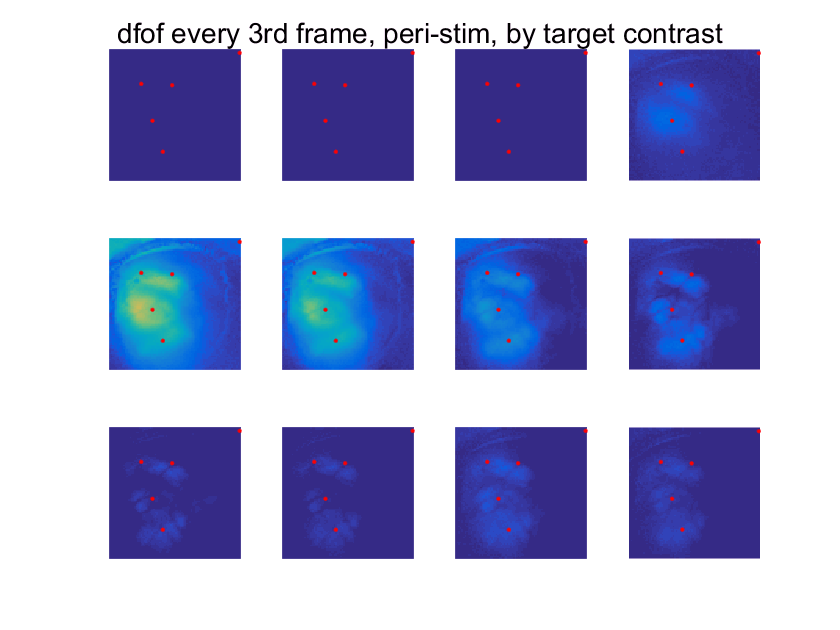

% plotting by target contrast 

% EE81LT needs trials-1 on 010621
    % update: when defining trials in the following loop -
    % tcTrial is a list of all trial conditions, in order.
    % But we don't want to take *all* of the trials at each contrast,
    % we want to leave out the ones that don't meet the criteria set out by the 
    % -10 +40 thing. We can't be indexing trials that are not in onsetDf because they
    % were removed earlier in onsets
    
    % trials is a list of all trial conditions in order for the c-th contrast
    % so let's redefine trials to only include columns (trial numbers)
    % that are equal to the values we used to index into the onset values 
    % that met the -10 +40 criteria (because the onsets is a list of frame 
    % values that are in order of trial)

clear c
contrasts = unique(tc); % go thru list of contrasts and take each value only once, make this a new vector
for c = 1:length(contrasts); % for each unique contrast
    figure
    suptitle('dfof every 3rd frame, peri-stim, by target contrast')
    %% trials =  abs(tcTrial)==contrasts(c); % confused... c-th unique contrast... make abs value of trial target condition equal contrast? then to  'c' contrast, then assign that to trials?
    % EE81LT needs trials-1 on 010621
    % update: conTrials is a list of all trial conditions, in order.
    % But we don't want to take *all* of the trials at each contrast,
    % we want to leave out the ones that don't meet the criteria set out by the 
    % -10 +40 thing. We can't be indexing trials that are not in onsetDf because they
    % were removed earlier in onsets [update: I redefined onsets earlier 
    % so it carried thru to onsetFrame & onsetDf 
    
    % trials is a list of all trial conditions in order for the c-th contrast
    % so let's redefine trials to only include columns that are equal to the values 
    % we used to index into the onset trials that met the -10 +40 criteria
    
    % let's do that by indexing into tcTrials - remember tcTrials are trial 
    % conditions in order of presentation. So if we take the columns that match
    % the trials that met the critera for onsets (which is the length of the 
    % number of trials and contains frame numbers)
    % then wesll have only the trial conditions for those trials that emt the criteria
    clear cthTrials
    cthTcTrialMeetCriteria = tcTrial(idxOnsetsMeetBothCriteria);
    cthTrials = cthTcTrialMeetCriteria==contrasts(c);
    
     set(gcf,'Name',sprintf('tc = %0.3f  n = %d',contrasts(c),sum(cthTrials)));
    for f = 1:12;
        subplot(3,4,f) 
        imagesc(mean(onsetDf(:,:,f*3,cthTrials),4)-mean(onsetDf(:,:,11,cthTrials),4) ,range); 
        hold on; plot(xpts,ypts,'r.')
        axis equal; axis off;
    end
end

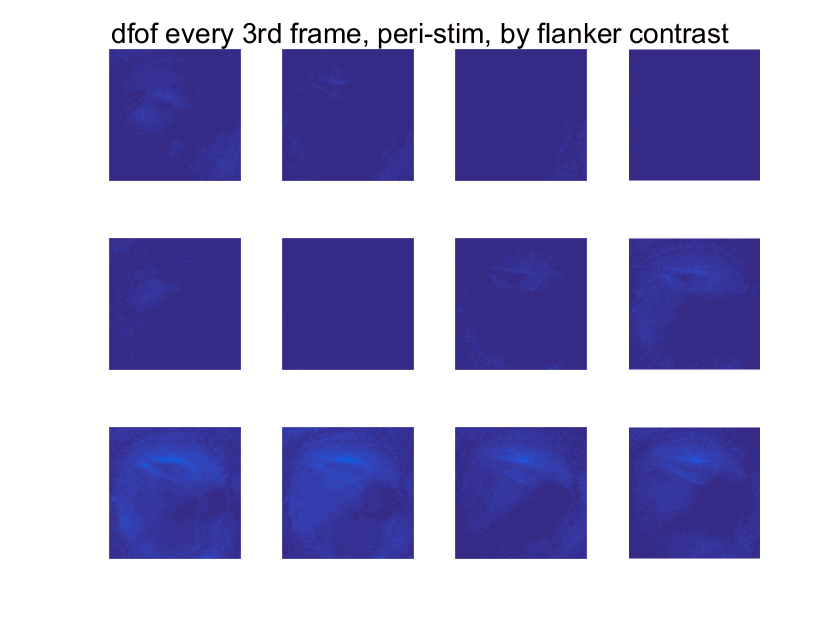

%%% plotting by flanker contrasts - all flanker contrasts are zero so I
%%% think this plot should be the same as the earlier one that's across all
contrasts = unique(abs(fc));
for c = 1:length(contrasts);
    figure
    suptitle('dfof every 3rd frame, peri-stim, by flanker contrast')
    
    cthTcTrialMeetCriteria = tcTrial(idxOnsetsMeetBothCriteria);
    cthTrials = cthTcTrialMeetCriteria==contrasts(c);
    
    set(gcf,'Name',sprintf('fc = %0.3f  n = %d',contrasts(c),sum(cthTrials)));
    for f = 1:12;
        subplot(3,4,f)
        imagesc(mean(onsetDf(:,:,f*3,cthTrials),4)-mean(onsetDf(:,:,11,cthTrials),4) ,range)
        axis equal; axis off
    end
end

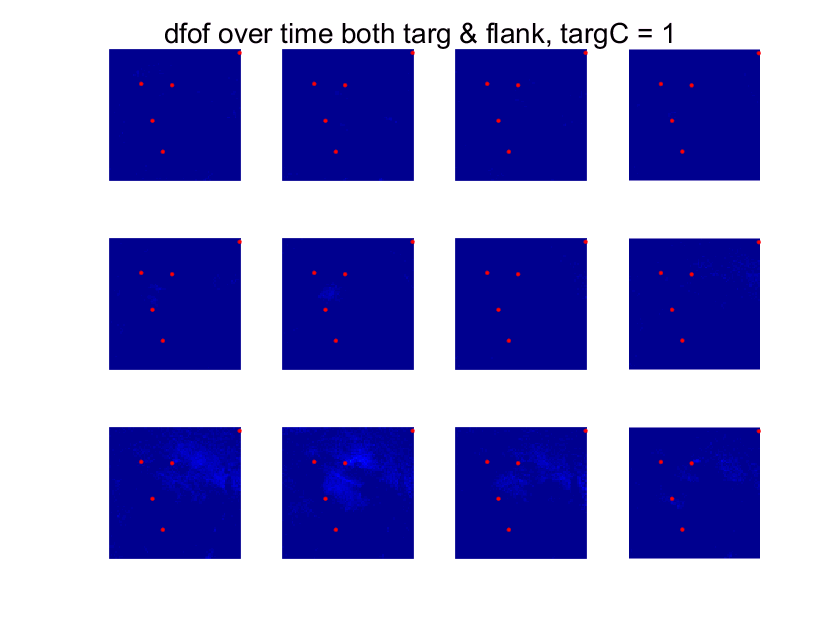

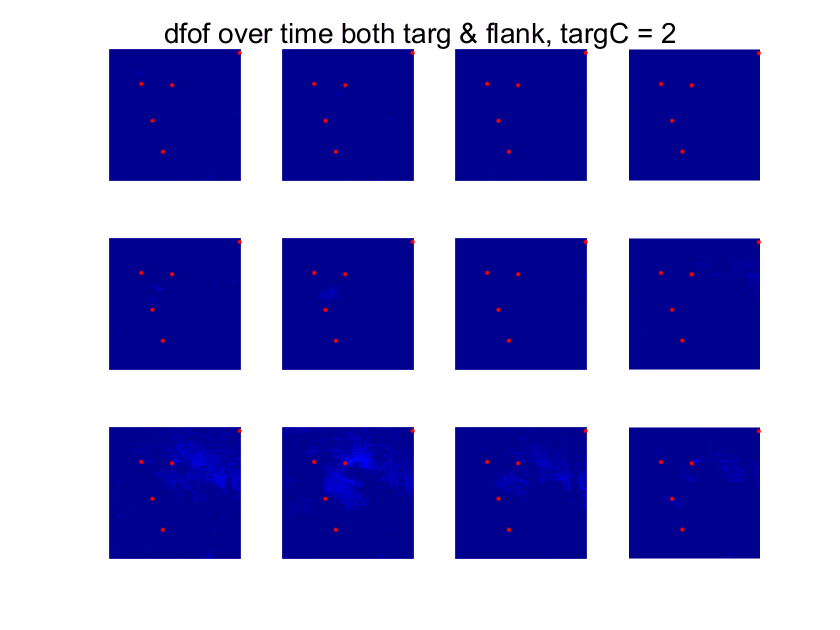

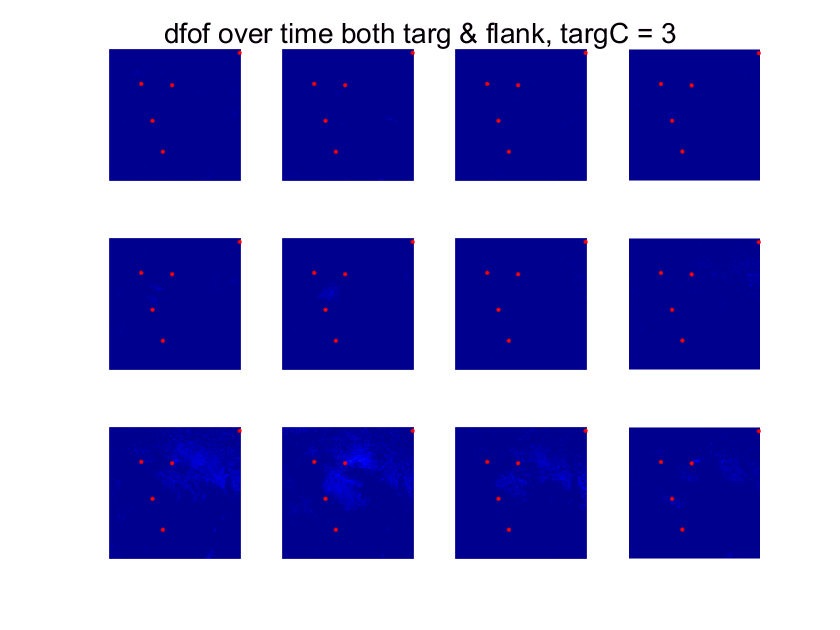

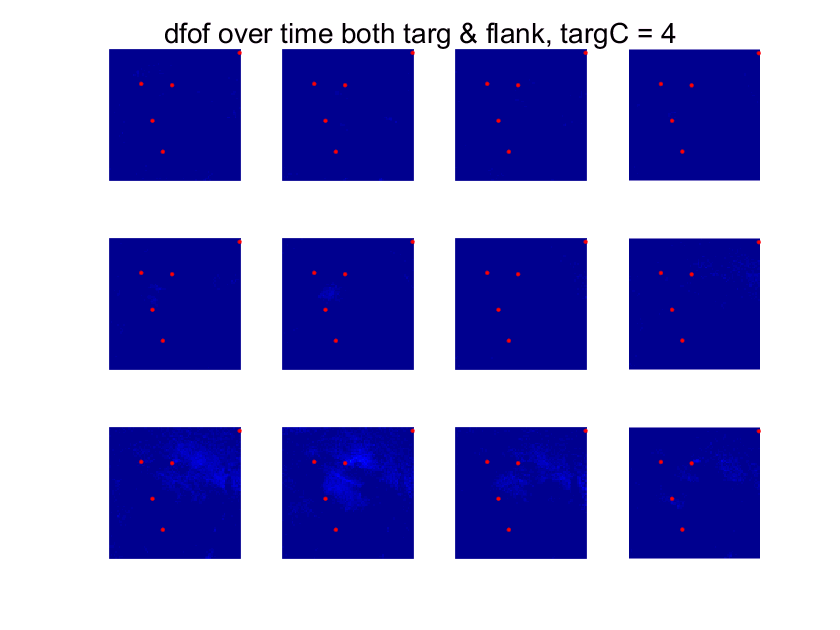

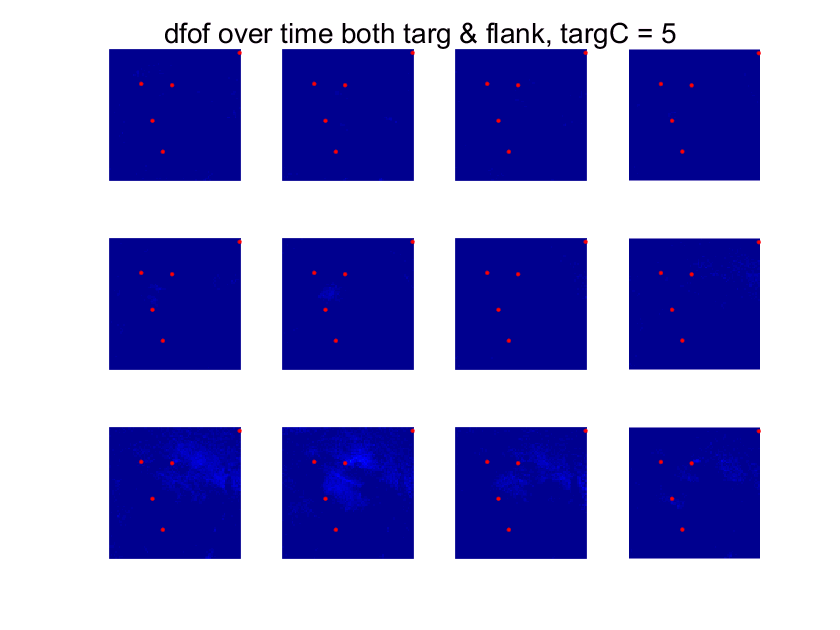

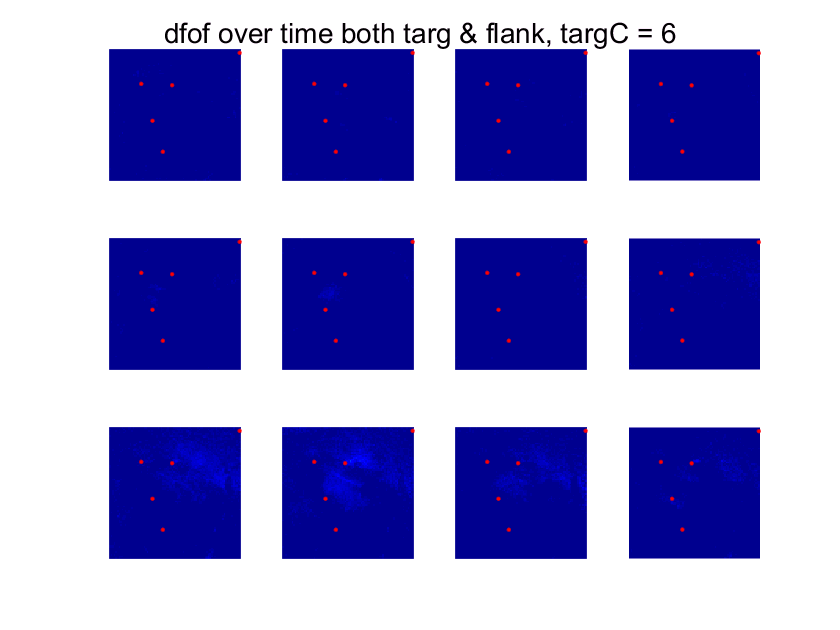

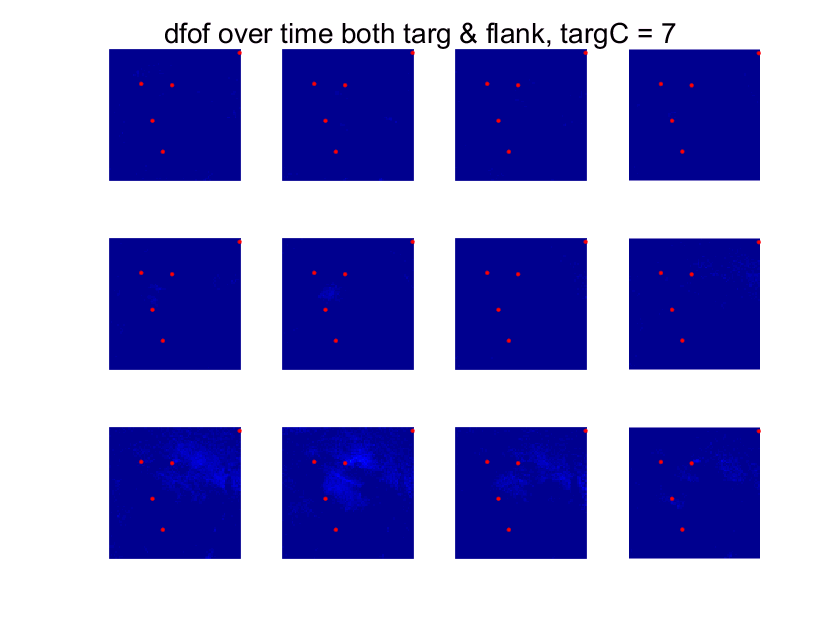

%%% full parameters = flanker and target

contrasts = unique(abs(fc));
tcontrasts = unique(tc);
for c = 1:length(contrasts);
    for c2= 1:length(tcontrasts)
% for c = [1 3];
%     for c2 = [1 3];

        cthTcTrialMeetCriteria = tcTrial(idxOnsetsMeetBothCriteria);
        cthTrials = cthTcTrialMeetCriteria==contrasts(c);
        figure
        suptitle(sprintf('dfof over time both targ & flank, targC = %d', c2))
        set(gcf,'Name',sprintf('fc = %0.3f tc = %0.3f n = %d',contrasts(c),tcontrasts(c2),sum(cthTrials)));
        for f = 1:12;
            subplot(3,4,f)
            % why median below instead of mean?
            imagesc(median(onsetDf(:,:,f*3,cthTrials),4)-mean(onsetDf(:,:,11,cthTrials),4) ,range) % what does range mean here
            axis equal; axis off
            hold on; 
            plot(xpts,ypts,'r.'); 
            colormap jet
        end
        % savefig(sprintf('EE8LT_020421_%d_imThreshPass',c2))
    end
end

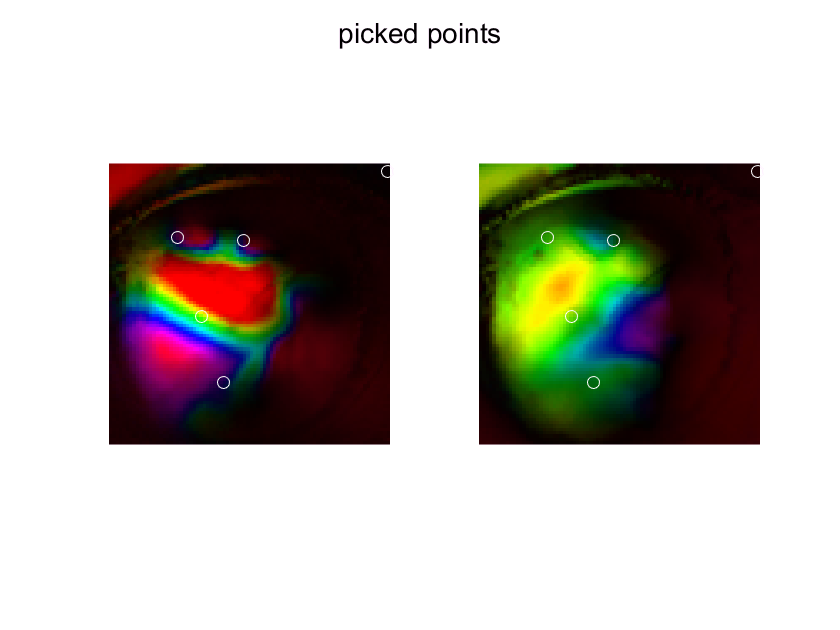

figure
suptitle('picked points')

subplot(1,2,1);
imshow(topox_crop); 
hold on; 
plot(xpts,ypts,'wo')

subplot(1,2,2);
imshow(topoy_crop);
hold on; 
plot(xpts,ypts,'wo')


% savefig('277RT_020421_picked_points')


% how is frameT in maps file different from frameT in allResp & allStop?
%save('277RT_020421_imThreshPass','xpts','ypts','onsetDf','stimDetails','df','topox','topoy','allResp','allStop','trialCond')
% save('277RT_031121_imThreshPass','xpts','ypts','onsetDf','stimDetails','idxOnsetsMeetBothCriteria','df','topox','topoy','allResp','allStop','trialCond')
